%In this script, the relations for predicting Wiebe parameters as well as fuel mass are developed.
%These correlations are used in the final model:"Numerical_Predictive_Model_FINAL".
%------------------------------------------------------------------------------------------------------------------------------------------------------------

%Load the example Wiebe parameter data at experimental test points, which is generated using the script called...
% "Wiebe_comparison". The data is saved in the folder: Example_Data\correlation variables. The user must use their own data
load('Example_Data\correlation variables\B00.mat','B00_dataW_HRR');
load('Example_Data\correlation variables\B05.mat','B05_dataW_HRR');
load('Example_Data\correlation variables\B15.mat','B15_dataW_HRR');
load('Example_Data\correlation variables\B20.mat','B20_dataW_HRR');
load('Example_Data\correlation variables\B50.mat','B50_dataW_HRR');
load('Example_Data\correlation variables\B100.mat','B100_dataW_HRR');


%Remove points 3000rpm_5nm because experimental SOC for this point cannot be calculated for B0,B15,B20,B50 and B100
% Define file-sheet combinations
    files_and_sheets = {
        '3000_20nm.xlsx', '3000_20nm';
        '3000_12nm.xlsx', '3000_12nm';
        %'3000_5nm.xlsx', '3000_5nm';
        '2500_20nm.xlsx', '2500_20nm';
        '2500_12nm.xlsx', '2500_12nm';
        '2500_5nm.xlsx', '2500_5nm';
        '2000_20nm.xlsx', '2000_20nm';
        '2000_12nm.xlsx', '2000_12nm';
        '2000_5nm.xlsx', '2000_5nm';
 }; 

B0

S_SOC_p_B00=ones(1,length(files_and_sheets)); %Single-Wiebe
S_DOC_p_B00=ones(1,length(files_and_sheets)); %Single-Wiebe
S_m_p_B00=ones(1,length(files_and_sheets)); %Single-Wiebe
S_b_p_B00=ones(1,length(files_and_sheets)); %Single-Wiebe

D_SOC_p_B00=ones(1,length(files_and_sheets)); %Double-Wiebe
D_DOC_p_B00=ones(1,length(files_and_sheets)); %Double-Wiebe
D_m_p_B00=ones(1,length(files_and_sheets)); %Double-Wiebe
D_b_p_B00=ones(1,length(files_and_sheets)); %Double-Wiebe
D_SOC_d_B00=ones(1,length(files_and_sheets)); %Double-Wiebe
D_DOC_d_B00=ones(1,length(files_and_sheets)); %Double-Wiebe
D_m_d_B00=ones(1,length(files_and_sheets)); %Double-Wiebe
D_b_d_B00=ones(1,length(files_and_sheets)); %Double-Wiebe
for i=1:length(files_and_sheets)
    filename=files_and_sheets{i,1};

    %create variable name from filename
    [~,VarName,~]=fileparts(filename);
    VarName=matlab.lang.makeValidName(['P_' VarName]);

    B00_dataW_HRR.(VarName);
    S_SOC_p_B00(i)=B00_dataW_HRR.(VarName){1,2};
    S_DOC_p_B00(i)=B00_dataW_HRR.(VarName){2,2};
    S_m_p_B00(i)=B00_dataW_HRR.(VarName){3,2};
    S_b_p_B00(i)=B00_dataW_HRR.(VarName){4,2};

    D_SOC_p_B00(i)=B00_dataW_HRR.(VarName){1,4};
    D_DOC_p_B00(i)=B00_dataW_HRR.(VarName){2,4};
    D_m_p_B00(i)=B00_dataW_HRR.(VarName){3,4};
    D_b_p_B00(i)=B00_dataW_HRR.(VarName){4,4};

    D_SOC_d_B00(i)=B00_dataW_HRR.(VarName){5,4};
    D_DOC_d_B00(i)=B00_dataW_HRR.(VarName){6,4};
    D_m_d_B00(i)=B00_dataW_HRR.(VarName){7,4};
    D_b_d_B00(i)=B00_dataW_HRR.(VarName){8,4};
end

B15

S_SOC_p_B15=ones(1,length(files_and_sheets)); %Single-Wiebe
S_DOC_p_B15=ones(1,length(files_and_sheets)); %Single-Wiebe
S_m_p_B15=ones(1,length(files_and_sheets)); %Single-Wiebe
S_b_p_B15=ones(1,length(files_and_sheets)); %Single-Wiebe

D_SOC_p_B15=ones(1,length(files_and_sheets)); %Double-Wiebe
D_DOC_p_B15=ones(1,length(files_and_sheets)); %Double-Wiebe
D_m_p_B15=ones(1,length(files_and_sheets)); %Double-Wiebe
D_b_p_B15=ones(1,length(files_and_sheets)); %Double-Wiebe
D_SOC_d_B15=ones(1,length(files_and_sheets)); %Double-Wiebe
D_DOC_d_B15=ones(1,length(files_and_sheets)); %Double-Wiebe
D_m_d_B15=ones(1,length(files_and_sheets)); %Double-Wiebe
D_b_d_B15=ones(1,length(files_and_sheets)); %Double-Wiebe
for i=1:length(files_and_sheets)
    filename=files_and_sheets{i,1};

    %create variable name from filename
    [~,VarName,~]=fileparts(filename);
    VarName=matlab.lang.makeValidName(['P_' VarName]);

    B15_dataW_HRR.(VarName);
    S_SOC_p_B15(i)=B15_dataW_HRR.(VarName){1,2};
    S_DOC_p_B15(i)=B15_dataW_HRR.(VarName){2,2};
    S_m_p_B15(i)=B15_dataW_HRR.(VarName){3,2};
    S_b_p_B15(i)=B15_dataW_HRR.(VarName){4,2};

    D_SOC_p_B15(i)=B15_dataW_HRR.(VarName){1,4};
    D_DOC_p_B15(i)=B15_dataW_HRR.(VarName){2,4};
    D_m_p_B15(i)=B15_dataW_HRR.(VarName){3,4};
    D_b_p_B15(i)=B15_dataW_HRR.(VarName){4,4};

    D_SOC_d_B15(i)=B15_dataW_HRR.(VarName){5,4};
    D_DOC_d_B15(i)=B15_dataW_HRR.(VarName){6,4};
    D_m_d_B15(i)=B15_dataW_HRR.(VarName){7,4};
    D_b_d_B15(i)=B15_dataW_HRR.(VarName){8,4};
end

B20

S_SOC_p_B20=ones(1,length(files_and_sheets)); %Single-Wiebe
S_DOC_p_B20=ones(1,length(files_and_sheets)); %Single-Wiebe
S_m_p_B20=ones(1,length(files_and_sheets)); %Single-Wiebe
S_b_p_B20=ones(1,length(files_and_sheets)); %Single-Wiebe

D_SOC_p_B20=ones(1,length(files_and_sheets)); %Double-Wiebe
D_DOC_p_B20=ones(1,length(files_and_sheets)); %Double-Wiebe
D_m_p_B20=ones(1,length(files_and_sheets)); %Double-Wiebe
D_b_p_B20=ones(1,length(files_and_sheets)); %Double-Wiebe
D_SOC_d_B20=ones(1,length(files_and_sheets)); %Double-Wiebe
D_DOC_d_B20=ones(1,length(files_and_sheets)); %Double-Wiebe
D_m_d_B20=ones(1,length(files_and_sheets)); %Double-Wiebe
D_b_d_B20=ones(1,length(files_and_sheets)); %Double-Wiebe
for i=1:length(files_and_sheets)
    filename=files_and_sheets{i,1};

    %create variable name from filename
    [~,VarName,~]=fileparts(filename);
    VarName=matlab.lang.makeValidName(['P_' VarName]);

    B20_dataW_HRR.(VarName);
    S_SOC_p_B20(i)=B20_dataW_HRR.(VarName){1,2};
    S_DOC_p_B20(i)=B20_dataW_HRR.(VarName){2,2};
    S_m_p_B20(i)=B20_dataW_HRR.(VarName){3,2};
    S_b_p_B20(i)=B20_dataW_HRR.(VarName){4,2};

    D_SOC_p_B20(i)=B20_dataW_HRR.(VarName){1,4};
    D_DOC_p_B20(i)=B20_dataW_HRR.(VarName){2,4};
    D_m_p_B20(i)=B20_dataW_HRR.(VarName){3,4};
    D_b_p_B20(i)=B20_dataW_HRR.(VarName){4,4};

    D_SOC_d_B20(i)=B20_dataW_HRR.(VarName){5,4};
    D_DOC_d_B20(i)=B20_dataW_HRR.(VarName){6,4};
    D_m_d_B20(i)=B20_dataW_HRR.(VarName){7,4};
    D_b_d_B20(i)=B20_dataW_HRR.(VarName){8,4};
end

B50

S_SOC_p_B50=ones(1,length(files_and_sheets)); %Single-Wiebe
S_DOC_p_B50=ones(1,length(files_and_sheets)); %Single-Wiebe
S_m_p_B50=ones(1,length(files_and_sheets)); %Single-Wiebe
S_b_p_B50=ones(1,length(files_and_sheets)); %Single-Wiebe

D_SOC_p_B50=ones(1,length(files_and_sheets)); %Double-Wiebe
D_DOC_p_B50=ones(1,length(files_and_sheets)); %Double-Wiebe
D_m_p_B50=ones(1,length(files_and_sheets)); %Double-Wiebe
D_b_p_B50=ones(1,length(files_and_sheets)); %Double-Wiebe
D_SOC_d_B50=ones(1,length(files_and_sheets)); %Double-Wiebe
D_DOC_d_B50=ones(1,length(files_and_sheets)); %Double-Wiebe
D_m_d_B50=ones(1,length(files_and_sheets)); %Double-Wiebe
D_b_d_B50=ones(1,length(files_and_sheets)); %Double-Wiebe
for i=1:length(files_and_sheets)
    filename=files_and_sheets{i,1};

    %create variable name from filename
    [~,VarName,~]=fileparts(filename);
    VarName=matlab.lang.makeValidName(['P_' VarName]);

    B50_dataW_HRR.(VarName);
    S_SOC_p_B50(i)=B50_dataW_HRR.(VarName){1,2};
    S_DOC_p_B50(i)=B50_dataW_HRR.(VarName){2,2};
    S_m_p_B50(i)=B50_dataW_HRR.(VarName){3,2};
    S_b_p_B50(i)=B50_dataW_HRR.(VarName){4,2};

    D_SOC_p_B50(i)=B50_dataW_HRR.(VarName){1,4};
    D_DOC_p_B50(i)=B50_dataW_HRR.(VarName){2,4};
    D_m_p_B50(i)=B50_dataW_HRR.(VarName){3,4};
    D_b_p_B50(i)=B50_dataW_HRR.(VarName){4,4};

    D_SOC_d_B50(i)=B50_dataW_HRR.(VarName){5,4};
    D_DOC_d_B50(i)=B50_dataW_HRR.(VarName){6,4};
    D_m_d_B50(i)=B50_dataW_HRR.(VarName){7,4};
    D_b_d_B50(i)=B50_dataW_HRR.(VarName){8,4};
end

B100

S_SOC_p_B100=ones(1,length(files_and_sheets)); %Single-Wiebe
S_DOC_p_B100=ones(1,length(files_and_sheets)); %Single-Wiebe
S_m_p_B100=ones(1,length(files_and_sheets)); %Single-Wiebe
S_b_p_B100=ones(1,length(files_and_sheets)); %Single-Wiebe

D_SOC_p_B100=ones(1,length(files_and_sheets)); %Double-Wiebe
D_DOC_p_B100=ones(1,length(files_and_sheets)); %Double-Wiebe
D_m_p_B100=ones(1,length(files_and_sheets)); %Double-Wiebe
D_b_p_B100=ones(1,length(files_and_sheets)); %Double-Wiebe
D_SOC_d_B100=ones(1,length(files_and_sheets)); %Double-Wiebe
D_DOC_d_B100=ones(1,length(files_and_sheets)); %Double-Wiebe
D_m_d_B100=ones(1,length(files_and_sheets)); %Double-Wiebe
D_b_d_B100=ones(1,length(files_and_sheets)); %Double-Wiebe
for i=1:length(files_and_sheets)
    filename=files_and_sheets{i,1};

    %create variable name from filename
    [~,VarName,~]=fileparts(filename);
    VarName=matlab.lang.makeValidName(['P_' VarName]);

    B100_dataW_HRR.(VarName);
    S_SOC_p_B100(i)=B100_dataW_HRR.(VarName){1,2};
    S_DOC_p_B100(i)=B100_dataW_HRR.(VarName){2,2};
    S_m_p_B100(i)=B100_dataW_HRR.(VarName){3,2};
    S_b_p_B100(i)=B100_dataW_HRR.(VarName){4,2};

    D_SOC_p_B100(i)=B100_dataW_HRR.(VarName){1,4};
    D_DOC_p_B100(i)=B100_dataW_HRR.(VarName){2,4};
    D_m_p_B100(i)=B100_dataW_HRR.(VarName){3,4};
    D_b_p_B100(i)=B100_dataW_HRR.(VarName){4,4};

    D_SOC_d_B100(i)=B100_dataW_HRR.(VarName){5,4};
    D_DOC_d_B100(i)=B100_dataW_HRR.(VarName){6,4};
    D_m_d_B100(i)=B100_dataW_HRR.(VarName){7,4};
    D_b_d_B100(i)=B100_dataW_HRR.(VarName){8,4};
end

B5

%Remove points 3000rpm_5nm because SOC for this point is wrong, and Remove
%2000rpm_20nm because experimental pressure is not successfully
%filtered
files_and_sheets = {
        '3000_20nm.xlsx', '3000_20nm';
        '3000_12nm.xlsx', '3000_12nm';
        %'3000_5nm.xlsx', '3000_5nm';
        '2500_20nm.xlsx', '2500_20nm';
        '2500_12nm.xlsx', '2500_12nm';
        '2500_5nm.xlsx', '2500_5nm';
        %'2000_20nm.xlsx', '2000_20nm';
        '2000_12nm.xlsx', '2000_12nm';
        '2000_5nm.xlsx', '2000_5nm';
 };
S_SOC_p_B05=ones(1,length(files_and_sheets)); %Single-Wiebe
S_DOC_p_B05=ones(1,length(files_and_sheets)); %Single-Wiebe
S_m_p_B05=ones(1,length(files_and_sheets)); %Single-Wiebe
S_b_p_B05=ones(1,length(files_and_sheets)); %Single-Wiebe

D_SOC_p_B05=ones(1,length(files_and_sheets)); %Double-Wiebe
D_DOC_p_B05=ones(1,length(files_and_sheets)); %Double-Wiebe
D_m_p_B05=ones(1,length(files_and_sheets)); %Double-Wiebe
D_b_p_B05=ones(1,length(files_and_sheets)); %Double-Wiebe
D_SOC_d_B05=ones(1,length(files_and_sheets)); %Double-Wiebe
D_DOC_d_B05=ones(1,length(files_and_sheets)); %Double-Wiebe
D_m_d_B05=ones(1,length(files_and_sheets)); %Double-Wiebe
D_b_d_B05=ones(1,length(files_and_sheets)); %Double-Wiebe
for i=1:length(files_and_sheets)
    filename=files_and_sheets{i,1};

    %create variable name from filename
    [~,VarName,~]=fileparts(filename);
    VarName=matlab.lang.makeValidName(['P_' VarName]);

    B05_dataW_HRR.(VarName);
    S_SOC_p_B05(i)=B05_dataW_HRR.(VarName){1,2};
    S_DOC_p_B05(i)=B05_dataW_HRR.(VarName){2,2};
    S_m_p_B05(i)=B05_dataW_HRR.(VarName){3,2};
    S_b_p_B05(i)=B05_dataW_HRR.(VarName){4,2};

    D_SOC_p_B05(i)=B05_dataW_HRR.(VarName){1,4};
    D_DOC_p_B05(i)=B05_dataW_HRR.(VarName){2,4};
    D_m_p_B05(i)=B05_dataW_HRR.(VarName){3,4};
    D_b_p_B05(i)=B05_dataW_HRR.(VarName){4,4};

    D_SOC_d_B05(i)=B05_dataW_HRR.(VarName){5,4};
    D_DOC_d_B05(i)=B05_dataW_HRR.(VarName){6,4};
    D_m_d_B05(i)=B05_dataW_HRR.(VarName){7,4};
    D_b_d_B05(i)=B05_dataW_HRR.(VarName){8,4};
end

N_05=[3000,3000,2500,2500,2500,2000,2000]; %Speed for B5
N_Rem=[3000,3000,2500,2500,2500,2000,2000,2000]; %Speed for remaining fuels
Speed=[N_Rem,N_05,N_Rem,N_Rem,N_Rem,N_Rem]; %Speed for all points
T_05=[20,12,20,12,5,12,5]; %Load/Torque for B5
T_rem=[20,12,20,12,5,20,12,5]; %Load/Torque for remaining points
Load=[T_rem,T_05,T_rem,T_rem,T_rem,T_rem]; %Load/Torque for all points
B0=zeros(1,8); B5=5*ones(1,7); B15=15*ones(1,8);B20=20*ones(1,8); B50=50*ones(1,8); B100=100*ones(1,8);
Fuel=[B0,B5,B15,B20,B50,B100]; %Vector of bioblend percentage in fuel for all points

%------------------------------------------------------------------------------------------------------------------------------------------------------------
S_SOC_p=[S_SOC_p_B00,S_SOC_p_B05,S_SOC_p_B15,S_SOC_p_B20,S_SOC_p_B50,S_SOC_p_B100];

% K-Fold Cross-Validation
k=7; % 5 fold cross-validation
n=length(S_SOC_p);
rng(42); 
indices = mod(randperm(n)-1, k) + 1; % Random assignment to folds 1:k
RMSE_S_SOC_folds = zeros(k, 1);
R2_S_SOC_folds = zeros(k, 1);

for i = 1:k
    % Split data
    validate_indx = (indices == i); %index for validation data
    train_indx = ~validate_indx; %index for training data
    %Build design matrix for training
    A=[ones(sum(train_indx),1),Speed(train_indx)',Load(train_indx)',Fuel(train_indx)',Speed(train_indx)'.^2,Load(train_indx)'.^2,...
    Fuel(train_indx)'.^2,Speed(train_indx)'.*Load(train_indx)',Speed(train_indx)'.*Fuel(train_indx)',Fuel(train_indx)'.*Load(train_indx)'...
    ,Speed(train_indx)'.*Load(train_indx)'.*Fuel(train_indx)'];

    %Fit model
    B=A\S_SOC_p(train_indx)';

    %Predict on validation data
    S_SOC_p_relation = @ (N,T,BP) B(1)+B(2).*N+B(3).*T+B(4).*BP+B(5).*N.^2+B(6).*T.^2+B(7).*BP.^2+B(8).*N.*T+B(9).*N.*BP+B(10).*BP.*T+B(11).*N.*T.*BP; %N=Speed, T=Torque, BP=Bioblend Percentage
    S_SOC_p_test=S_SOC_p_relation(Speed(validate_indx)',Load(validate_indx)',Fuel(validate_indx)');

    %Calculate statistical metrics
    RMSE_S_SOC_folds(i)=RMSE(S_SOC_p_test,S_SOC_p(validate_indx)');
    R2_S_SOC_folds(i)=R2(S_SOC_p_test,S_SOC_p(validate_indx)');
end
% Report average performance
fprintf('Mean RMSE: %.4f ± %.4f\n', mean(RMSE_S_SOC_folds), std(RMSE_S_SOC_folds)); %standard deviation tells us how far the data is distributed from mean

Mean RMSE: 0.2974 ± 0.0740


fprintf('Mean R²: %.4f ± %.4f\n', mean(R2_S_SOC_folds), std(R2_S_SOC_folds));

Mean R²: 0.6092 ± 0.7322


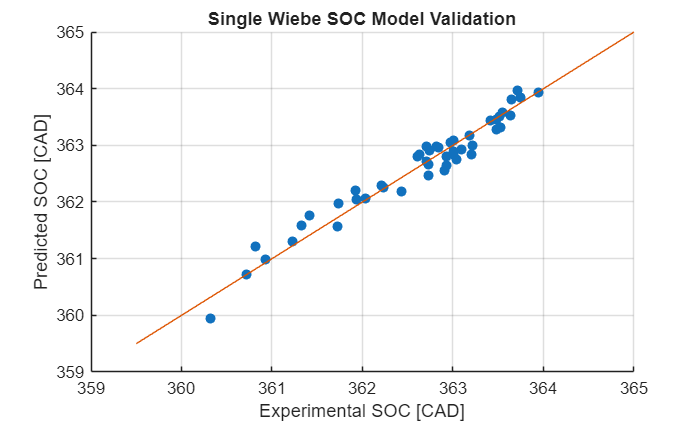

%Final model
A=[ones(n,1),Speed',Load',Fuel',Speed'.^2,Load'.^2,Fuel'.^2,Speed'.*Load',Speed'.*Fuel',Fuel'.*Load',Speed'.*Load'.*Fuel'];

%Fit model
B_S_SOC_p=A\S_SOC_p';

S_SOC_p_test=A*B_S_SOC_p;

y=@ (x) x; %straight line with zero slope
x=linspace(359.5,365,50);

figure
scatter(S_SOC_p,S_SOC_p_test, 'filled');hold on;
plot(x,y(x));
xlabel('Experimental SOC [CAD]')
ylabel('Predicted SOC [CAD]')
title('Single Wiebe SOC Model Validation')
grid on
hold off;


%--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
D_SOC_p=[D_SOC_p_B00,D_SOC_p_B05,D_SOC_p_B15,D_SOC_p_B20,D_SOC_p_B50,D_SOC_p_B100];

% K-Fold Cross-Validation
k=7; % 5 fold cross-validation
n=length(D_SOC_p);
indices = mod(randperm(n)-1, k) + 1; % Random assignment to folds 1:k
RMSE_D_SOCp_folds = zeros(k, 1);
R2_D_SOCp_folds = zeros(k, 1);

for i = 1:k
    % Split data
    validate_indx = (indices == i); %index for validation data
    train_indx = ~validate_indx; %index for training data
    %Build design matrix for training
    A=[ones(sum(train_indx),1),Speed(train_indx)',Load(train_indx)',Fuel(train_indx)',Speed(train_indx)'.^2,Load(train_indx)'.^2,...
    Fuel(train_indx)'.^2,Speed(train_indx)'.*Load(train_indx)',Speed(train_indx)'.*Fuel(train_indx)',Fuel(train_indx)'.*Load(train_indx)']; 

    %Fit model
    B=A\D_SOC_p(train_indx)';

    %Predict on validation data
    D_SOC_p_relation = @ (N,T,BP) B(1)+B(2).*N+B(3).*T+B(4).*BP+B(5).*N.^2+B(6).*T.^2+B(7).*BP.^2+B(8).*N.*T+B(9).*N.*BP+B(10).*BP.*T; %N=Speed, T=Torque, BP=Bioblend Percentage
    D_SOC_p_test=D_SOC_p_relation(Speed(validate_indx)',Load(validate_indx)',Fuel(validate_indx)');

    %Calculate statistical metrics
    RMSE_D_SOCp_folds(i)=RMSE(D_SOC_p_test,D_SOC_p(validate_indx)');
    R2_D_SOCp_folds(i)=R2(D_SOC_p_test,D_SOC_p(validate_indx)');
end
% Report average performance
fprintf('Mean RMSE: %.4f ± %.4f\n', mean(RMSE_D_SOCp_folds), std(RMSE_D_SOCp_folds)); %standard deviation tells us how far the data is distributed from mean

Mean RMSE: 0.4702 ± 0.1725


fprintf('Mean R²: %.4f ± %.4f\n', mean(R2_D_SOCp_folds), std(R2_D_SOCp_folds));

Mean R²: -0.0205 ± 0.9346


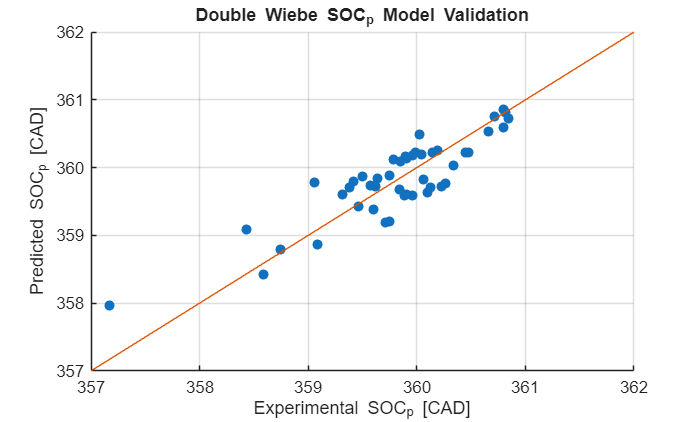

%Final model
A=[ones(n,1),Speed',Load',Fuel',Speed'.^2,Load'.^2,Fuel'.^2,Speed'.*Load',Speed'.*Fuel',Fuel'.*Load'];

%Fit model
B_D_SOC_p=A\D_SOC_p';

D_SOC_p_test=A*B_D_SOC_p;

y=@ (x) x; %straight line with zero slope
x=linspace(357,362,50);

figure
scatter(D_SOC_p,D_SOC_p_test, 'filled');hold on;
plot(x,y(x));
xlabel('Experimental SOC_p [CAD]')
ylabel('Predicted SOC_p [CAD]')
title('Double Wiebe SOC_p Model Validation')
grid on
hold off;

%-------------------------------------------------------------------------------------------------------------------------------------------------------------
D_SOC_d=[D_SOC_d_B00,D_SOC_d_B05,D_SOC_d_B15,D_SOC_d_B20,D_SOC_d_B50,D_SOC_d_B100];

% K-Fold Cross-Validation
k=7; % 5 fold cross-validation
n=length(D_SOC_d);
indices = mod(randperm(n)-1, k) + 1; % Random assignment to folds 1:k
RMSE_D_SOCd_folds = zeros(k, 1);
R2_D_SOCd_folds = zeros(k, 1);

for i = 1:k
    % Split data
    validate_indx = (indices == i); %index for validation data
    train_indx = ~validate_indx; %index for training data
    %Build design matrix for training
    A=[ones(sum(train_indx),1),Speed(train_indx)',Load(train_indx)',Fuel(train_indx)',Speed(train_indx)'.^2,Load(train_indx)'.^2,...
    Fuel(train_indx)'.^2,Speed(train_indx)'.*Load(train_indx)',Speed(train_indx)'.*Fuel(train_indx)',Fuel(train_indx)'.*Load(train_indx)']; 

    %Fit model
    B=A\D_SOC_d(train_indx)';

    %Predict on validation data
    D_SOC_d_relation = @ (N,T,BP) B(1)+B(2).*N+B(3).*T+B(4).*BP+B(5).*N.^2+B(6).*T.^2+B(7).*BP.^2+B(8).*N.*T+B(9).*N.*BP+B(10).*BP.*T; %N=Speed, T=Torque, BP=Bioblend Percentage
    D_SOC_d_test=D_SOC_d_relation(Speed(validate_indx)',Load(validate_indx)',Fuel(validate_indx)');

    %Calculate statistical metrics
    RMSE_D_SOCd_folds(i)=RMSE(D_SOC_d_test,D_SOC_d(validate_indx)');
    R2_D_SOCd_folds(i)=R2(D_SOC_d_test,D_SOC_d(validate_indx)');
end
% Report average performance
fprintf('Mean RMSE: %.4f ± %.4f\n', mean(RMSE_D_SOCd_folds), std(RMSE_D_SOCd_folds)); %standard deviation tells us how far the data is distributed from mean

Mean RMSE: 0.3148 ± 0.0861


fprintf('Mean R²: %.4f ± %.4f\n', mean(R2_D_SOCd_folds), std(R2_D_SOCd_folds));

Mean R²: -0.2034 ± 0.9856


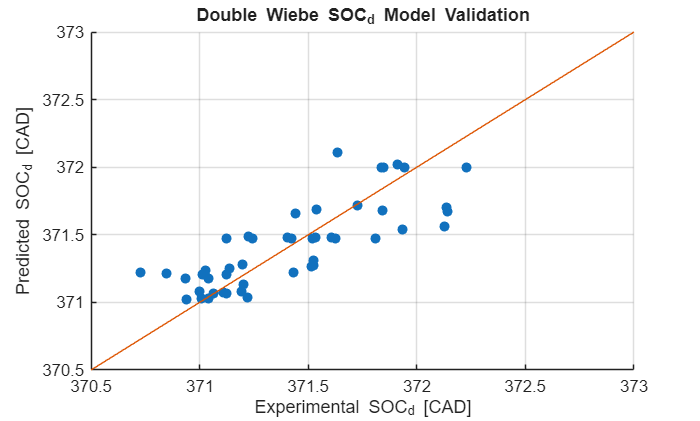

%Final model
A=[ones(n,1),Speed',Load',Fuel',Speed'.^2,Load'.^2,Fuel'.^2,Speed'.*Load',Speed'.*Fuel',Fuel'.*Load'];

%Fit model
B_D_SOC_d=A\D_SOC_d';

D_SOC_d_test=A*B_D_SOC_d;

y=@ (x) x; %straight line with zero slope
x=linspace(370.5,373,50);

figure
scatter(D_SOC_d,D_SOC_d_test, 'filled');hold on;
plot(x,y(x));
xlabel('Experimental SOC_d [CAD]')
ylabel('Predicted SOC_d [CAD]')
title('Double Wiebe SOC_d Model Validation')
grid on
hold off;

%--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
S_DOC_p=[S_DOC_p_B00,S_DOC_p_B05,S_DOC_p_B15,S_DOC_p_B20,S_DOC_p_B50,S_DOC_p_B100];

% K-Fold Cross-Validation
k=7; % 5 fold cross-validation
n=length(S_DOC_p);
indices = mod(randperm(n)-1, k) + 1; % Random assignment to folds 1:k
RMSE_S_DOC_folds = zeros(k, 1);
R2_S_DOC_folds = zeros(k, 1);

for i = 1:k
    % Split data
    validate_indx = (indices == i); %index for validation data
    train_indx = ~validate_indx; %index for training data
    %Build design matrix for training
    A=[ones(sum(train_indx),1),Speed(train_indx)',Load(train_indx)',Fuel(train_indx)',Speed(train_indx)'.^2,Load(train_indx)'.^2,...
    Fuel(train_indx)'.^2,Speed(train_indx)'.*Load(train_indx)',Speed(train_indx)'.*Fuel(train_indx)',Fuel(train_indx)'.*Load(train_indx)'...
    ,Speed(train_indx)'.*Load(train_indx)'.*Fuel(train_indx)'];

    %Fit model
    B=A\S_DOC_p(train_indx)';

    %Predict on validation data
    S_DOC_p_relation = @ (N,T,BP) B(1)+B(2).*N+B(3).*T+B(4).*BP+B(5).*N.^2+B(6).*T.^2+B(7).*BP.^2+B(8).*N.*T+B(9).*N.*BP+B(10).*BP.*T+B(11).*N.*T.*BP; %N=Speed, T=Torque, BP=Bioblend Percentage
    S_DOC_p_test=S_DOC_p_relation(Speed(validate_indx)',Load(validate_indx)',Fuel(validate_indx)');

    %Calculate statistical metrics
    RMSE_S_DOC_folds(i)=RMSE(S_DOC_p_test,S_DOC_p(validate_indx)');
    R2_S_DOC_folds(i)=R2(S_DOC_p_test,S_DOC_p(validate_indx)');
end
% Report average performance
fprintf('Mean RMSE: %.4f ± %.4f\n', mean(RMSE_S_DOC_folds), std(RMSE_S_DOC_folds)); %standard deviation tells us how far the data is distributed from mean

Mean RMSE: 3.6405 ± 1.5418


fprintf('Mean R²: %.4f ± %.4f\n', mean(R2_S_DOC_folds), std(R2_S_DOC_folds));

Mean R²: 0.8657 ± 0.1319


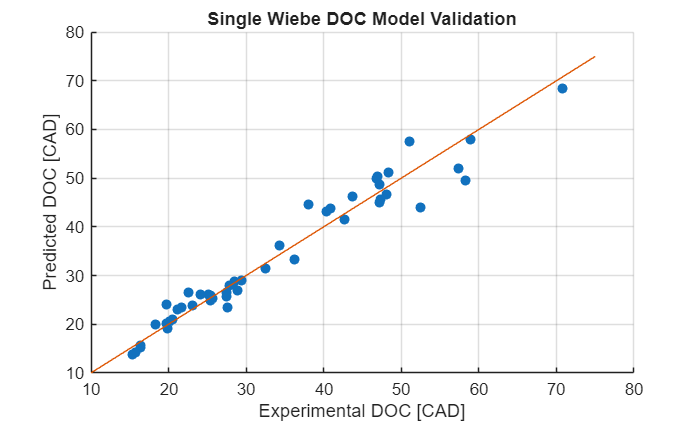

%Final model
A=[ones(n,1),Speed',Load',Fuel',Speed'.^2,Load'.^2,Fuel'.^2,Speed'.*Load',Speed'.*Fuel',Fuel'.*Load',Speed'.*Load'.*Fuel'];

%Fit model
B_S_DOC_p=A\S_DOC_p';

S_DOC_p_test=A*B_S_DOC_p;

y=@ (x) x; %straight line with zero slope
x=linspace(10,75,50);

figure
scatter(S_DOC_p,S_DOC_p_test, 'filled');hold on;
plot(x,y(x));
xlabel('Experimental DOC [CAD]')
ylabel('Predicted DOC [CAD]')
title('Single Wiebe DOC Model Validation')
grid on
hold off;

%-------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
D_DOC_p=[D_DOC_p_B00,D_DOC_p_B05,D_DOC_p_B15,D_DOC_p_B20,D_DOC_p_B50,D_DOC_p_B100];

% K-Fold Cross-Validation
k=7; % 5 fold cross-validation
n=length(D_DOC_p);
indices = mod(randperm(n)-1, k) + 1; % Random assignment to folds 1:k
RMSE_D_DOCp_folds = zeros(k, 1);
R2_D_DOCp_folds = zeros(k, 1);

for i = 1:k
    % Split data
    validate_indx = (indices == i); %index for validation data
    train_indx = ~validate_indx; %index for training data
    %Build design matrix for training
    A=[ones(sum(train_indx),1),Speed(train_indx)',Load(train_indx)',Fuel(train_indx)',Speed(train_indx)'.^2,Load(train_indx)'.^2,...
    Fuel(train_indx)'.^2,Speed(train_indx)'.*Load(train_indx)',Speed(train_indx)'.*Fuel(train_indx)',Fuel(train_indx)'.*Load(train_indx)'];

    %Fit model
    B=A\D_DOC_p(train_indx)';

    %Predict on validation data
    D_DOC_p_relation = @ (N,T,BP) B(1)+B(2).*N+B(3).*T+B(4).*BP+B(5).*N.^2+B(6).*T.^2+B(7).*BP.^2+B(8).*N.*T+B(9).*N.*BP+B(10).*BP.*T; %N=Speed, T=Torque, BP=Bioblend Percentage
    D_DOC_p_test=D_DOC_p_relation(Speed(validate_indx)',Load(validate_indx)',Fuel(validate_indx)');

    %Calculate statistical metrics
    RMSE_D_DOCp_folds(i)=RMSE(D_DOC_p_test,D_DOC_p(validate_indx)');
    R2_D_DOCp_folds(i)=R2(D_DOC_p_test,D_DOC_p(validate_indx)');
end
% Report average performance
fprintf('Mean RMSE: %.4f ± %.4f\n', mean(RMSE_D_DOCp_folds), std(RMSE_D_DOCp_folds)); %standard deviation tells us how far the data is distributed from mean

Mean RMSE: 0.9489 ± 0.5132


fprintf('Mean R²: %.4f ± %.4f\n', mean(R2_D_DOCp_folds), std(R2_D_DOCp_folds));

Mean R²: 0.7565 ± 0.1684


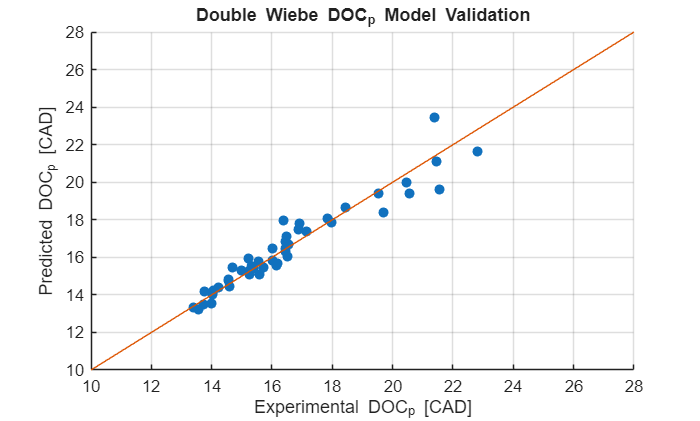

%Final model
A=[ones(n,1),Speed',Load',Fuel',Speed'.^2,Load'.^2,Fuel'.^2,Speed'.*Load',Speed'.*Fuel',Fuel'.*Load'];

%Fit model
B_D_DOC_p=A\D_DOC_p';

D_DOC_p_test=A*B_D_DOC_p;

y=@ (x) x; %straight line with zero slope
x=linspace(10,28,50);

figure
scatter(D_DOC_p,D_DOC_p_test, 'filled');hold on;
plot(x,y(x));
xlabel('Experimental DOC_p [CAD]')
ylabel('Predicted DOC_p [CAD]')
title('Double Wiebe DOC_p Model Validation')
grid on
hold off;

%------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
D_DOC_d=[D_DOC_d_B00,D_DOC_d_B05,D_DOC_d_B15,D_DOC_d_B20,D_DOC_d_B50,D_DOC_d_B100];

% K-Fold Cross-Validation
k=7; % 5 fold cross-validation
n=length(D_DOC_d);
indices = mod(randperm(n)-1, k) + 1; % Random assignment to folds 1:k
RMSE_D_DOCd_folds = zeros(k, 1);
R2_D_DOCd_folds = zeros(k, 1);

for i = 1:k
    % Split data
    validate_indx = (indices == i); %index for validation data
    train_indx = ~validate_indx; %index for training data
    %Build design matrix for training
    A=[ones(sum(train_indx),1),Speed(train_indx)',Load(train_indx)',Fuel(train_indx)',Speed(train_indx)'.^2,Load(train_indx)'.^2,...
    Fuel(train_indx)'.^2,Speed(train_indx)'.*Load(train_indx)',Speed(train_indx)'.*Fuel(train_indx)',Fuel(train_indx)'.*Load(train_indx)'];

    %Fit model
    B=A\D_DOC_d(train_indx)';

    %Predict on validation data
    D_DOC_d_relation = @ (N,T,BP) B(1)+B(2).*N+B(3).*T+B(4).*BP+B(5).*N.^2+B(6).*T.^2+B(7).*BP.^2+B(8).*N.*T+B(9).*N.*BP+B(10).*BP.*T; %N=Speed, T=Torque, BP=Bioblend Percentage
    D_DOC_d_test=D_DOC_d_relation(Speed(validate_indx)',Load(validate_indx)',Fuel(validate_indx)');

    %Calculate statistical metrics
    RMSE_D_DOCd_folds(i)=RMSE(D_DOC_d_test,D_DOC_d(validate_indx)');
    R2_D_DOCd_folds(i)=R2(D_DOC_d_test,D_DOC_d(validate_indx)');
end
% Report average performance
fprintf('Mean RMSE: %.4f ± %.4f\n', mean(RMSE_D_DOCd_folds), std(RMSE_D_DOCd_folds)); %standard deviation tells us how far the data is distributed from mean

Mean RMSE: 4.7493 ± 1.7070


fprintf('Mean R²: %.4f ± %.4f\n', mean(R2_D_DOCd_folds), std(R2_D_DOCd_folds));

Mean R²: 0.7643 ± 0.0990


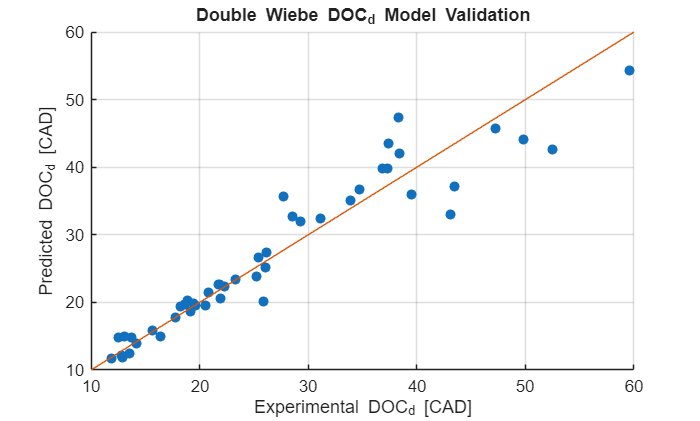

%Final model
A=[ones(n,1),Speed',Load',Fuel',Speed'.^2,Load'.^2,Fuel'.^2,Speed'.*Load',Speed'.*Fuel',Fuel'.*Load'];

%Fit model
B_D_DOC_d=A\D_DOC_d';

D_DOC_d_test=A*B_D_DOC_d;

y=@ (x) x; %straight line with zero slope
x=linspace(10,60,50);

figure
scatter(D_DOC_d,D_DOC_d_test, 'filled');hold on;
plot(x,y(x));
xlabel('Experimental DOC_d [CAD]')
ylabel('Predicted DOC_d [CAD]')
title('Double Wiebe DOC_d Model Validation')
grid on
hold off;


%-------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
S_m_p=[S_m_p_B00,S_m_p_B05,S_m_p_B15,S_m_p_B20,S_m_p_B50,S_m_p_B100];

% K-Fold Cross-Validation
k=7; % 5 fold cross-validation
n=length(S_m_p);
indices = mod(randperm(n)-1, k) + 1; % Random assignment to folds 1:k
RMSE_S_mp_folds = zeros(k, 1);
R2_S_mp_folds = zeros(k, 1);

for i = 1:k
    % Split data
    validate_indx = (indices == i); %index for validation data
    train_indx = ~validate_indx; %index for training data
    %Build design matrix for training
    A=[ones(sum(train_indx),1),Speed(train_indx)',Load(train_indx)',Fuel(train_indx)',Speed(train_indx)'.^2,Load(train_indx)'.^2,...
    Fuel(train_indx)'.^2,Speed(train_indx)'.*Load(train_indx)',Speed(train_indx)'.*Fuel(train_indx)',Fuel(train_indx)'.*Load(train_indx)'];

    %Fit model
    B=A\S_m_p(train_indx)';

    %Predict on validation data
    S_m_p_relation = @ (N,T,BP) B(1)+B(2).*N+B(3).*T+B(4).*BP+B(5).*N.^2+B(6).*T.^2+B(7).*BP.^2+B(8).*N.*T+B(9).*N.*BP+B(10).*BP.*T; %N=Speed, T=Torque, BP=Bioblend Percentage
    S_m_p_test=S_m_p_relation(Speed(validate_indx)',Load(validate_indx)',Fuel(validate_indx)');

    %Calculate statistical metrics
    RMSE_S_mp_folds(i)=RMSE(S_m_p_test,S_m_p(validate_indx)');
    R2_S_mp_folds(i)=R2(S_m_p_test,S_m_p(validate_indx)');
end
% Report average performance
fprintf('Mean RMSE: %.4f ± %.4f\n', mean(RMSE_S_mp_folds), std(RMSE_S_mp_folds)); %standard deviation tells us how far the data is distributed from mean

Mean RMSE: 0.0599 ± 0.0107


fprintf('Mean R²: %.4f ± %.4f\n', mean(R2_S_mp_folds), std(R2_S_mp_folds));

Mean R²: 0.7452 ± 0.2155


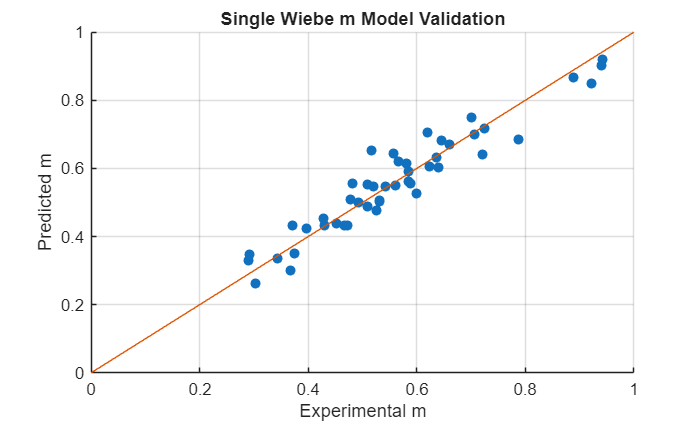

%Final model
A=[ones(n,1),Speed',Load',Fuel',Speed'.^2,Load'.^2,Fuel'.^2,Speed'.*Load',Speed'.*Fuel',Fuel'.*Load'];

%Fit model
B_S_m_p=A\S_m_p';

S_m_p_test=A*B_S_m_p;

y=@ (x) x; %straight line with zero slope
x=linspace(0,1,50);

figure
scatter(S_m_p,S_m_p_test, 'filled');hold on;
plot(x,y(x));
xlabel('Experimental m')
ylabel('Predicted m')
title('Single Wiebe m Model Validation')
grid on
hold off;

%-------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
D_m_p=[D_m_p_B00,D_m_p_B05,D_m_p_B15,D_m_p_B20,D_m_p_B50,D_m_p_B100];

% K-Fold Cross-Validation
k=7; % 5 fold cross-validation
n=length(D_m_p);
indices = mod(randperm(n)-1, k) + 1; % Random assignment to folds 1:k
RMSE_D_mp_folds = zeros(k, 1);
R2_D_mp_folds = zeros(k, 1);

for i = 1:k
    % Split data
    validate_indx = (indices == i); %index for validation data
    train_indx = ~validate_indx; %index for training data
    %Build design matrix for training
    A=[ones(sum(train_indx),1),Speed(train_indx)',Load(train_indx)',Fuel(train_indx)',Speed(train_indx)'.^2,Load(train_indx)'.^2,...
    Fuel(train_indx)'.^2,Speed(train_indx)'.*Load(train_indx)',Speed(train_indx)'.*Fuel(train_indx)',Fuel(train_indx)'.*Load(train_indx)'];

    %Fit model
    B=A\D_m_p(train_indx)';

    %Predict on validation data
    D_m_p_relation = @ (N,T,BP) B(1)+B(2).*N+B(3).*T+B(4).*BP+B(5).*N.^2+B(6).*T.^2+B(7).*BP.^2+B(8).*N.*T+B(9).*N.*BP+B(10).*BP.*T; %N=Speed, T=Torque, BP=Bioblend Percentage
    D_m_p_test=D_m_p_relation(Speed(validate_indx)',Load(validate_indx)',Fuel(validate_indx)');

    %Calculate statistical metrics
    RMSE_D_mp_folds(i)=RMSE(D_m_p_test,D_m_p(validate_indx)');
    R2_D_mp_folds(i)=R2(D_m_p_test,D_m_p(validate_indx)');
end
% Report average performance
fprintf('Mean RMSE: %.4f ± %.4f\n', mean(RMSE_D_mp_folds), std(RMSE_D_mp_folds)); %standard deviation tells us how far the data is distributed from mean

Mean RMSE: 0.2692 ± 0.1288


fprintf('Mean R²: %.4f ± %.4f\n', mean(R2_D_mp_folds), std(R2_D_mp_folds));

Mean R²: 0.3369 ± 0.4314


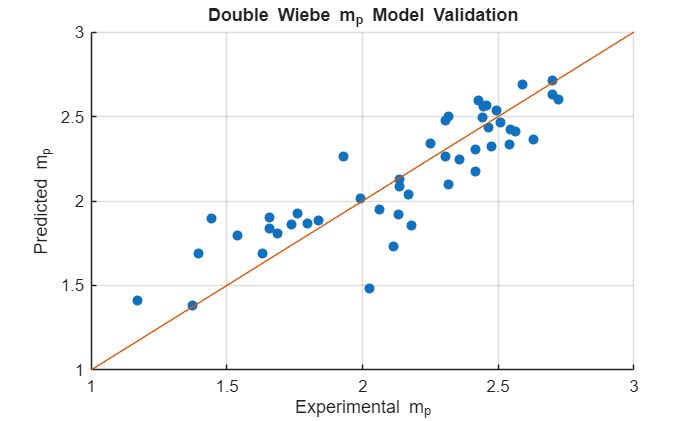

%Final model
A=[ones(n,1),Speed',Load',Fuel',Speed'.^2,Load'.^2,Fuel'.^2,Speed'.*Load',Speed'.*Fuel',Fuel'.*Load'];

%Fit model
B_D_m_p=A\D_m_p';

D_m_p_test=A*B_D_m_p;

y=@ (x) x; %straight line with zero slope
x=linspace(1,3,50);

figure
scatter(D_m_p,D_m_p_test, 'filled');hold on;
plot(x,y(x));
xlabel('Experimental m_p')
ylabel('Predicted m_p')
title('Double Wiebe m_p Model Validation')
grid on
hold off;

%------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
D_m_d=[D_m_d_B00,D_m_d_B05,D_m_d_B15,D_m_d_B20,D_m_d_B50,D_m_d_B100];

% K-Fold Cross-Validation
k=7; % 5 fold cross-validation
n=length(D_m_d);
indices = mod(randperm(n)-1, k) + 1; % Random assignment to folds 1:k
RMSE_D_md_folds = zeros(k, 1);
R2_D_md_folds = zeros(k, 1);

for i = 1:k
    % Split data
    validate_indx = (indices == i); %index for validation data
    train_indx = ~validate_indx; %index for training data
    %Build design matrix for training
    A=[ones(sum(train_indx),1),Speed(train_indx)',Load(train_indx)',Fuel(train_indx)',Speed(train_indx)'.^2,Load(train_indx)'.^2,...
    Fuel(train_indx)'.^2,Speed(train_indx)'.*Load(train_indx)',Speed(train_indx)'.*Fuel(train_indx)',Fuel(train_indx)'.*Load(train_indx)'];

    %Fit model
    B=A\D_m_d(train_indx)';

    %Predict on validation data
    D_m_d_relation = @ (N,T,BP) B(1)+B(2).*N+B(3).*T+B(4).*BP+B(5).*N.^2+B(6).*T.^2+B(7).*BP.^2+B(8).*N.*T+B(9).*N.*BP+B(10).*BP.*T; %N=Speed, T=Torque, BP=Bioblend Percentage
    D_m_d_test=D_m_d_relation(Speed(validate_indx)',Load(validate_indx)',Fuel(validate_indx)');

    %Calculate statistical metrics
    RMSE_D_md_folds(i)=RMSE(D_m_d_test,D_m_d(validate_indx)');
    R2_D_md_folds(i)=R2(D_m_d_test,D_m_d(validate_indx)');
end
% Report average performance
fprintf('Mean RMSE: %.4f ± %.4f\n', mean(RMSE_D_md_folds), std(RMSE_D_md_folds)); %standard deviation tells us how far the data is distributed from mean

Mean RMSE: 0.0880 ± 0.0201


fprintf('Mean R²: %.4f ± %.4f\n', mean(R2_D_md_folds), std(R2_D_md_folds));

Mean R²: 0.7316 ± 0.2333


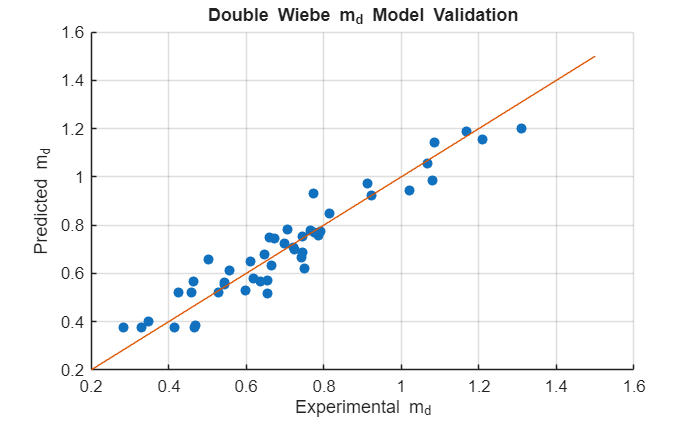

%Final model
A=[ones(n,1),Speed',Load',Fuel',Speed'.^2,Load'.^2,Fuel'.^2,Speed'.*Load',Speed'.*Fuel',Fuel'.*Load'];

%Fit model
B_D_m_d=A\D_m_d';

D_m_d_test=A*B_D_m_d;

y=@ (x) x; %straight line with zero slope
x=linspace(0.2,1.5,50);

figure
scatter(D_m_d,D_m_d_test, 'filled');hold on;
plot(x,y(x));
xlabel('Experimental m_d')
ylabel('Predicted m_d')
title('Double Wiebe m_d Model Validation')
grid on
hold off;


%-------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
S_b_p=[S_b_p_B00,S_b_p_B05,S_b_p_B15,S_b_p_B20,S_b_p_B50,S_b_p_B100];

% K-Fold Cross-Validation
k=7; % 5 fold cross-validation
n=length(S_b_p);
indices = mod(randperm(n)-1, k) + 1; % Random assignment to folds 1:k
RMSE_S_b_folds = zeros(k, 1);
R2_S_b_folds = zeros(k, 1);

for i = 1:k
    % Split data
    validate_indx = (indices == i); %index for validation data
    train_indx = ~validate_indx; %index for training data
    %Build design matrix for training
    A=[ones(sum(train_indx),1),Speed(train_indx)',Load(train_indx)',Fuel(train_indx)',Speed(train_indx)'.^2,Load(train_indx)'.^2,...
    Fuel(train_indx)'.^2,Speed(train_indx)'.*Load(train_indx)',Speed(train_indx)'.*Fuel(train_indx)',Fuel(train_indx)'.*Load(train_indx)'...
    ,Speed(train_indx)'.*Load(train_indx)'.*Fuel(train_indx)'];

    %Fit model
    B=A\S_b_p(train_indx)';

    %Predict on validation data
    S_b_p_relation = @ (N,T,BP) B(1)+B(2).*N+B(3).*T+B(4).*BP+B(5).*N.^2+B(6).*T.^2+B(7).*BP.^2+B(8).*N.*T+B(9).*N.*BP+B(10).*BP.*T+B(11).*N.*T.*BP; %N=Speed, T=Torque, BP=Bioblend Percentage
    S_b_p_test=S_b_p_relation(Speed(validate_indx)',Load(validate_indx)',Fuel(validate_indx)');

    %Calculate statistical metrics
    RMSE_S_b_folds(i)=RMSE(S_b_p_test,S_b_p(validate_indx)');
    R2_S_b_folds(i)=R2(S_b_p_test,S_b_p(validate_indx)');
end
% Report average performance
fprintf('Mean RMSE: %.4f ± %.4f\n', mean(RMSE_S_b_folds), std(RMSE_S_b_folds)); %standard deviation tells us how far the data is distributed from mean

Mean RMSE: 0.1099 ± 0.0436


fprintf('Mean R²: %.4f ± %.4f\n', mean(R2_S_b_folds), std(R2_S_b_folds));

Mean R²: -1.1497 ± 2.4166


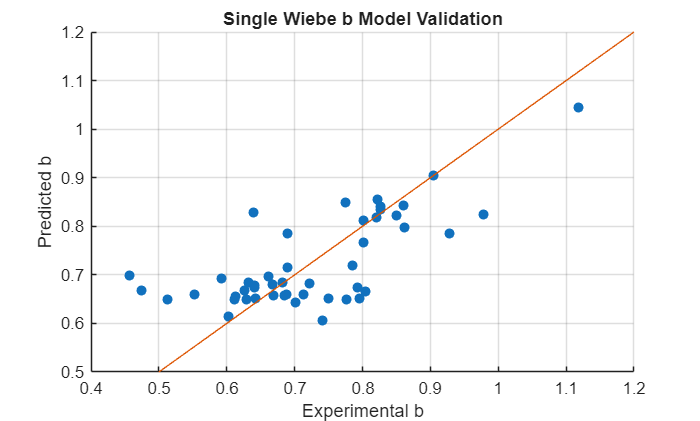

%Final model
A=[ones(n,1),Speed',Load',Fuel',Speed'.^2,Load'.^2,Fuel'.^2,Speed'.*Load',Speed'.*Fuel',Fuel'.*Load',Speed'.*Load'.*Fuel'];

%Fit model
B_S_b_p=A\S_b_p';

S_b_p_test=A*B_S_b_p;

y=@ (x) x; %straight line with zero slope
x=linspace(0.5,1.2,50);

figure
scatter(S_b_p,S_b_p_test, 'filled');hold on;
plot(x,y(x));
xlabel('Experimental b')
ylabel('Predicted b')
title('Single Wiebe b Model Validation')
grid on
hold off;

%--------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
D_b_p=[D_b_p_B00,D_b_p_B05,D_b_p_B15,D_b_p_B20,D_b_p_B50,D_b_p_B100];

% K-Fold Cross-Validation
k=7; % 5 fold cross-validation
n=length(D_b_p);
indices = mod(randperm(n)-1, k) + 1; % Random assignment to folds 1:k
RMSE_D_bp_folds = zeros(k, 1);
R2_D_bp_folds = zeros(k, 1);

for i = 1:k
    % Split data
    validate_indx = (indices == i); %index for validation data
    train_indx = ~validate_indx; %index for training data
    %Build design matrix for training
    A=[ones(sum(train_indx),1),Speed(train_indx)',Load(train_indx)',Fuel(train_indx)',Speed(train_indx)'.^2,Load(train_indx)'.^2,...
    Fuel(train_indx)'.^2,Speed(train_indx)'.*Load(train_indx)',Speed(train_indx)'.*Fuel(train_indx)',Fuel(train_indx)'.*Load(train_indx)'...
    ,Speed(train_indx)'.*Load(train_indx)'.*Fuel(train_indx)'];

    %Fit model
    B=A\D_b_p(train_indx)';

    %Predict on validation data
    D_b_p_relation = @ (N,T,BP) B(1)+B(2).*N+B(3).*T+B(4).*BP+B(5).*N.^2+B(6).*T.^2+B(7).*BP.^2+B(8).*N.*T+B(9).*N.*BP+B(10).*BP.*T+B(11).*N.*T.*BP; %N=Speed, T=Torque, BP=Bioblend Percentage
    D_b_p_test=D_b_p_relation(Speed(validate_indx)',Load(validate_indx)',Fuel(validate_indx)');

    %Calculate statistical metrics
    RMSE_D_bp_folds(i)=RMSE(D_b_p_test,D_b_p(validate_indx)');
    R2_D_bp_folds(i)=R2(D_b_p_test,D_b_p(validate_indx)');
end
% Report average performance
fprintf('Mean RMSE: %.4f ± %.4f\n', mean(RMSE_D_bp_folds), std(RMSE_D_bp_folds)); %standard deviation tells us how far the data is distributed from mean

Mean RMSE: 0.0909 ± 0.0250


fprintf('Mean R²: %.4f ± %.4f\n', mean(R2_D_bp_folds), std(R2_D_bp_folds));

Mean R²: 0.2903 ± 0.7075


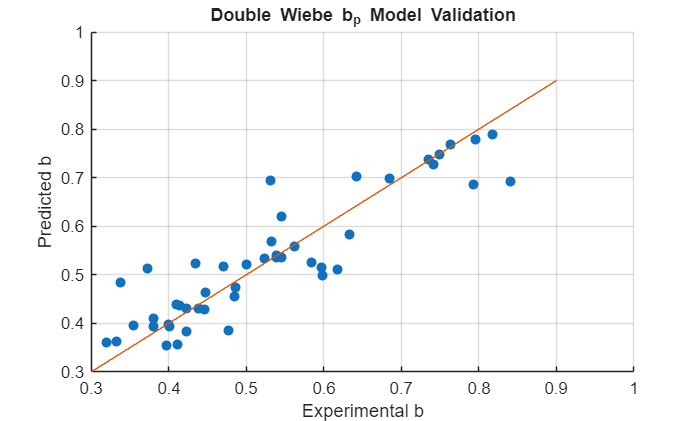

%Final model
A=[ones(n,1),Speed',Load',Fuel',Speed'.^2,Load'.^2,Fuel'.^2,Speed'.*Load',Speed'.*Fuel',Fuel'.*Load',Speed'.*Load'.*Fuel'];

%Fit model
B_D_b_p=A\D_b_p';

D_b_p_test=A*B_D_b_p;

y=@ (x) x; %straight line with zero slope
x=linspace(0.3,0.9,50);

figure
scatter(D_b_p,D_b_p_test, 'filled');hold on;
plot(x,y(x));
xlabel('Experimental b')
ylabel('Predicted b')
title('Double Wiebe b_p Model Validation')
grid on
hold off;

%-----------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
D_b_d=[D_b_d_B00,D_b_d_B05,D_b_d_B15,D_b_d_B20,D_b_d_B50,D_b_d_B100];

% K-Fold Cross-Validation
k=7; % 5 fold cross-validation
n=length(D_b_d);
indices = mod(randperm(n)-1, k) + 1; % Random assignment to folds 1:k
RMSE_D_bd_folds = zeros(k, 1);
R2_D_bd_folds = zeros(k, 1);

for i = 1:k
    % Split data
    validate_indx = (indices == i); %index for validation data
    train_indx = ~validate_indx; %index for training data
    %Build design matrix for training
    A=[ones(sum(train_indx),1),Speed(train_indx)',Load(train_indx)',Fuel(train_indx)',Speed(train_indx)'.^2,Load(train_indx)'.^2,...
    Fuel(train_indx)'.^2,Speed(train_indx)'.*Load(train_indx)',Speed(train_indx)'.*Fuel(train_indx)',Fuel(train_indx)'.*Load(train_indx)'...
    ,Speed(train_indx)'.*Load(train_indx)'.*Fuel(train_indx)'];

    %Fit model
    B=A\D_b_d(train_indx)';

    %Predict on validation data
    D_b_d_relation = @ (N,T,BP) B(1)+B(2).*N+B(3).*T+B(4).*BP+B(5).*N.^2+B(6).*T.^2+B(7).*BP.^2+B(8).*N.*T+B(9).*N.*BP+B(10).*BP.*T+B(11).*N.*T.*BP; %N=Speed, T=Torque, BP=Bioblend Percentage
    D_b_d_test=D_b_d_relation(Speed(validate_indx)',Load(validate_indx)',Fuel(validate_indx)');

    %Calculate statistical metrics
    RMSE_D_bd_folds(i)=RMSE(D_b_d_test,D_b_d(validate_indx)');
    R2_D_bd_folds(i)=R2(D_b_d_test,D_b_d(validate_indx)');
end
% Report average performance
fprintf('Mean RMSE: %.4f ± %.4f\n', mean(RMSE_D_bd_folds), std(RMSE_D_bd_folds)); %standard deviation tells us how far the data is distributed from mean

Mean RMSE: 0.0444 ± 0.0167


fprintf('Mean R²: %.4f ± %.4f\n', mean(R2_D_bd_folds), std(R2_D_bd_folds));

Mean R²: 0.4110 ± 0.4810


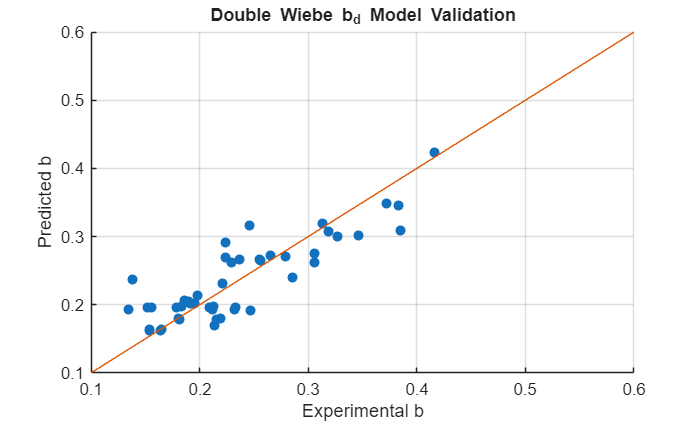

%Final model
A=[ones(n,1),Speed',Load',Fuel',Speed'.^2,Load'.^2,Fuel'.^2,Speed'.*Load',Speed'.*Fuel',Fuel'.*Load',Speed'.*Load'.*Fuel'];

%Fit model
B_D_b_d=A\D_b_d';

D_b_d_test=A*B_D_b_d;

y=@ (x) x; %straight line with zero slope
x=linspace(0.1,0.6,50);

figure
scatter(D_b_d,D_b_d_test, 'filled');hold on;
plot(x,y(x));
xlabel('Experimental b')
ylabel('Predicted b')
title('Double Wiebe b_d Model Validation')
grid on
hold off;

%-------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------
%Mass of fuel charge
N_V = [3000,3000,3000,2500,2500,2500,2000,2000,2000]; % Speed Vector in RPM
Load_V=[20,12,5,20,12,5,20,12,5]; %Load Vector in Nm

Mfdot_B100=[0.50286;0.34714;0.23498;0.38095;0.45596;0.24343;0.31769;0.21809;0.15146]./1000; %Mass flow rate of fuel (kg/s)
Mfdot_B50=[0.40952;0.38053;0.15693;0.47514;0.24677;0.15221;0.34331;0.23562;0.15765]./1000; %Mass flow rate of fuel (kg/s)
Mfdot_B20=[0.504762;0.33452;0.22493;0.37857;0.27712;0.15089;0.31524;0.23887;0.15762]./1000; %Mass flow rate of fuel (kg/s)
Mfdot_B15=[0.53544;0.28824;0.21609;0.42090;0.23598;0.15798;0.29580;0.21071;0.15080]./1000; %Mass flow rate of fuel (kg/s);
Mfdot_B05=[0.41174;0.25134;0.21899;0.39346;0.24656;0.14643;0.30563;0.20048;0.11204]./1000; %Mass flow rate of fuel (kg/s);
Mfdot_B00=[0.42532;0.27815;0.16503;0.38710;0.27496;0.14141;0.29016;0.18813;0.12017]./1000; %Mass flow rate of fuel (kg/s);

Mf_B100=ones(1,length(N_V));
Mf_B50=ones(1,length(N_V));
Mf_B20=ones(1,length(N_V));
Mf_B15=ones(1,length(N_V));
Mf_B05=ones(1,length(N_V));
Mf_B00=ones(1,length(N_V));

for i=1:length(N_V)
    charges_per_sec = (N_V(i)/60)/2;

    Mf_B100(i)=Mfdot_B100(i)/charges_per_sec;%Mass of fuel in each cycle (kg)
    Mf_B50(i)=Mfdot_B50(i)/charges_per_sec;%Mass of fuel in each cycle (kg)
    Mf_B20(i)=Mfdot_B20(i)/charges_per_sec;%Mass of fuel in each cycle (kg)
    Mf_B15(i)=Mfdot_B15(i)/charges_per_sec;%Mass of fuel in each cycle (kg)
    Mf_B05(i)=Mfdot_B05(i)/charges_per_sec;%Mass of fuel in each cycle (kg)
    Mf_B00(i)=Mfdot_B00(i)/charges_per_sec;%Mass of fuel in each cycle (kg)
end

Mf=[Mf_B00,Mf_B05,Mf_B15,Mf_B20,Mf_B50,Mf_B100]; %fuel mass/cyle for all points
Speed=[N_V,N_V,N_V,N_V,N_V,N_V]; %Speed for all points
Load=[Load_V,Load_V,Load_V,Load_V,Load_V,Load_V]; %Load for all points
B0=zeros(1,9); B5=5*ones(1,9); B15=15*ones(1,9);B20=20*ones(1,9); B50=50*ones(1,9); B100=100*ones(1,9);
Fuel=[B0,B5,B15,B20,B50,B100]; %Vector of bioblend percentage in fuel for all points

% K-Fold Cross-Validation
k=7; % 5 fold cross-validation
n=length(Mf);
indices = mod(randperm(n)-1, k) + 1; % Random assignment to folds 1:k
RMSE_Mf_folds = zeros(k, 1);
R2_Mf_folds = zeros(k, 1);

for i = 1:k
    % Split data
    validate_indx = (indices == i); %index for validation data
    train_indx = ~validate_indx; %index for training data
    %Build design matrix for training
    A=[ones(sum(train_indx),1),Speed(train_indx)',Load(train_indx)',Fuel(train_indx)'];

    %Fit model
    B=A\Mf(train_indx)';

    %Predict on validation data
    Mf_relation = @ (N,T,BP) B(1)+B(2).*N+B(3).*T+B(4).*BP; %N=Speed, T=Torque, BP=Bioblend Percentage
    Mf_test=Mf_relation(Speed(validate_indx)',Load(validate_indx)',Fuel(validate_indx)');

    %Calculate statistical metrics
    RMSE_Mf_folds(i)=RMSE(Mf_test,Mf(validate_indx)');
    R2_Mf_folds(i)=R2(Mf_test,Mf(validate_indx)');
end

% Report average performance
fprintf('Mean RMSE: %.4f ± %.4f\n', mean(RMSE_Mf_folds), std(RMSE_Mf_folds)); %standard deviation tells us how far the data is distributed from mean

Mean RMSE: 0.0000 ± 0.0000


fprintf('Mean R²: %.4f ± %.4f\n', mean(R2_Mf_folds), std(R2_Mf_folds));

Mean R²: 0.8520 ± 0.0847


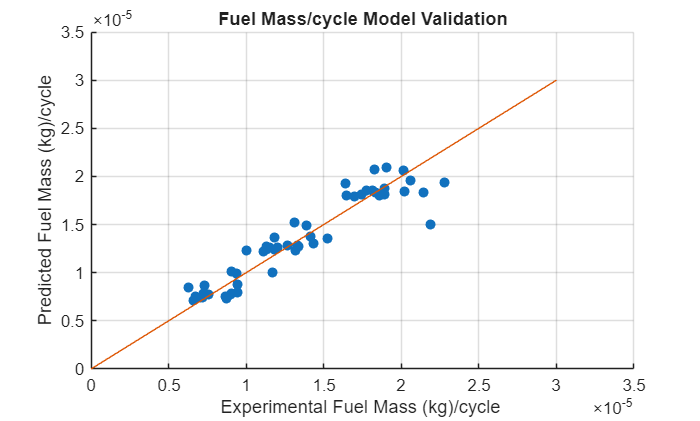


%Final Model
A=[ones(length(Mf),1),Speed',Load',Fuel'];
B_Mf=A\Mf'; %Solution of coefficients 

Mf_test=A*B_Mf;

y=@ (x) x; %straight line with zero slope
x=linspace(0,0.3e-4,50);

figure
scatter(Mf,Mf_test, 'filled');hold on;
plot(x,y(x));
xlabel('Experimental Fuel Mass (kg)/cycle ')
ylabel('Predicted Fuel Mass (kg)/cycle')
title('Fuel Mass/cycle Model Validation')
grid on
hold off;

T=table([B_D_SOC_p;0],[B_D_SOC_d;0],[B_D_DOC_p;0],[B_D_DOC_d;0],[B_D_m_p;0],[B_D_m_d;0],B_D_b_p,B_D_b_d,[B_Mf;0;0;0;0;0;0;0],...
    'VariableNames',{'SOC_p','SOC_d','DOC_p','DOC_d','m_p','m_d','b_p','b_d','fuel mass'},...
    'RowNames',{'B0','B1','B2','B3','B4','B5','B6','B7','B8','B9','B10'}) 

T = 11×9 table
              SOC_p          SOC_d          DOC_p         DOC_d           m_p            m_d            b_p            b_d         fuel mass 
           ___________    ___________    ___________    __________    ___________    ___________    ___________    ___________    ___________

    B0          363.23         375.33         7.1756        63.706         2.3243       -0.87645        0.36728        0.71782     4.4177e-06
    B1      0.00031516     -0.0046035      0.0017575     -0.035282    -2.1799e-05      0.0014868     0.00025825    -0.00037209    -2.8376e-10
    B2        -0.53198        0.19317        0.80375       

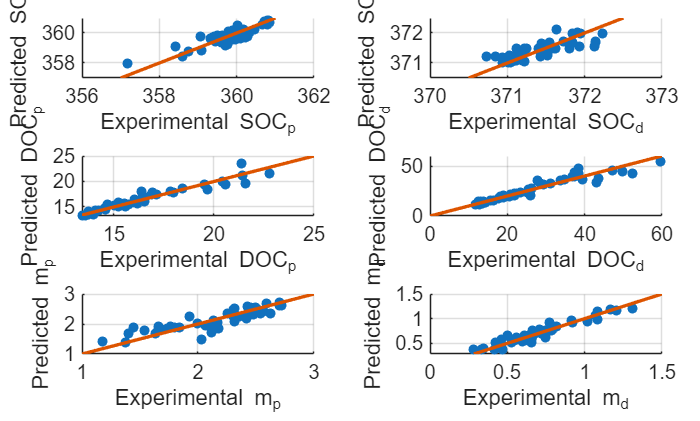

% figure
% scatter(D_SOC_p,D_SOC_p_test, 'filled');hold on;
% refline(1,0);
% xlabel('Experimental SOC_p [CAD]')
% ylabel('Predicted SOC_p [CAD]')
% title('Double Wiebe SOC_p Model Validation')
% grid on
% hold off;

% % First plot (top-left)
% ax1 = nexttile;
% scatter(D_SOC_p, D_SOC_p_test, 'filled'); hold on
% r = refline(1,0);
% r.Color = [0.2 0.2 0.2]; % dark gray
% r.LineStyle = '--';
% r.LineWidth = 1.2;
% grid on
% xlabel('Experimental SOC')
% ylabel('Predicted SOC')
% ax1.FontSize = 12;
% title("Woschni");

figure;
% Create a 2x2 tiled layout
t = tiledlayout(3,2);
t.TileSpacing = 'compact';
t.Padding = 'compact';

% First plot (top-left)
ax1=nexttile;
scatter(D_SOC_p,D_SOC_p_test, 'filled');hold on
r=refline(1,0);
r.LineWidth = 2;
xlabel('Experimental SOC_p')
ylabel('Predicted SOC_p')
ax1.FontSize = 12;
ax1.FontSize = 12;
grid('on')
% Second plot (top-left)
ax2=nexttile;
scatter(D_SOC_d,D_SOC_d_test, 'filled');hold on
r=refline(1,0);
r.LineWidth = 2;
xlabel('Experimental SOC_d')
ylabel('Predicted SOC_d')
ax2.FontSize = 12;
ax2.FontSize = 12;
grid('on')
% First plot (top-left)
ax3=nexttile;
scatter(D_DOC_p,D_DOC_p_test, 'filled');hold on
r=refline(1,0);
r.LineWidth = 2;
xlabel('Experimental DOC_p')
ylabel('Predicted DOC_p')
ax3.FontSize = 12;
ax3.FontSize = 12;
grid('on')
% Second plot (top-left)
ax4=nexttile;
scatter(D_DOC_d,D_DOC_d_test, 'filled');hold on
r=refline(1,0);
r.LineWidth = 2;
xlabel('Experimental DOC_d')
ylabel('Predicted DOC_d')
ax4.FontSize = 12;
ax4.FontSize = 12;
grid('on')
% First plot (top-left)
ax5=nexttile;
scatter(D_m_p,D_m_p_test, 'filled');hold on
r=refline(1,0);
r.LineWidth = 2;
xlabel('Experimental m_p')
ylabel('Predicted m_p')
ax5.FontSize = 12;
ax5.FontSize = 12;
grid('on')
% Second plot (top-left)
ax6=nexttile;
scatter(D_m_d,D_m_d_test, 'filled');hold on
r=refline(1,0);
r.LineWidth = 2;
xlabel('Experimental m_d')
ylabel('Predicted m_d')
ax6.FontSize = 12;
ax6.FontSize = 12;
grid('on')

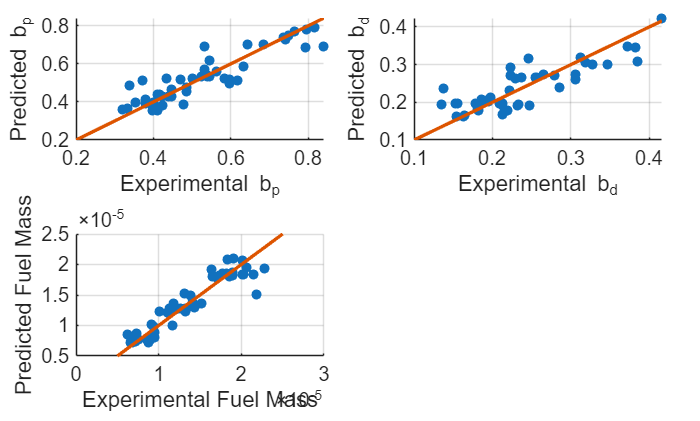


figure;
% Create a 2x2 tiled layout
t = tiledlayout(2,2);
t.TileSpacing = 'compact';
t.Padding = 'compact';
% First plot (top-left)
ax1=nexttile;
scatter(D_b_p,D_b_p_test, 'filled');hold on
r=refline(1,0);
r.LineWidth = 2;
xlabel('Experimental b_p')
ylabel('Predicted b_p')
ax1.FontSize = 12;
ax1.FontSize = 12;
grid('on')
% Second plot (top-left)
ax2=nexttile;
scatter(D_b_d,D_b_d_test, 'filled');hold on
r=refline(1,0);
r.LineWidth = 2;
xlabel('Experimental b_d')
ylabel('Predicted b_d')
ax2.FontSize = 12;
ax2.FontSize = 12;
grid('on')
% First plot (top-left)
ax3=nexttile;
scatter(Mf,Mf_test, 'filled');hold on;
r=refline(1,0);
r.LineWidth = 2;
xlabel('Experimental Fuel Mass')
ylabel('Predicted Fuel Mass')
ax3.FontSize = 12;
ax3.FontSize = 12;
grid('on')

fprintf('Mean RMSE: %.4f ± %.4f\n', mean(RMSE_D_SOCp_folds), std(RMSE_D_SOCp_folds));

Mean RMSE: 0.4702 ± 0.1725


fprintf('Mean RMSE: %.4f ± %.4f\n', mean(RMSE_D_SOCd_folds), std(RMSE_D_SOCd_folds));

Mean RMSE: 0.3148 ± 0.0861


fprintf('Mean RMSE: %.4f ± %.4f\n', mean(RMSE_D_DOCp_folds), std(RMSE_D_DOCp_folds));

Mean RMSE: 0.9489 ± 0.5132


fprintf('Mean RMSE: %.4f ± %.4f\n', mean(RMSE_D_DOCd_folds), std(RMSE_D_DOCd_folds));

Mean RMSE: 4.7493 ± 1.7070


fprintf('Mean RMSE: %.4f ± %.4f\n', mean(RMSE_D_mp_folds), std(RMSE_D_mp_folds));

Mean RMSE: 0.2692 ± 0.1288


fprintf('Mean RMSE: %.4f ± %.4f\n', mean(RMSE_D_md_folds), std(RMSE_D_md_folds));

Mean RMSE: 0.0880 ± 0.0201


fprintf('Mean RMSE: %.4f ± %.4f\n', mean(RMSE_D_bp_folds), std(RMSE_D_bp_folds));

Mean RMSE: 0.0909 ± 0.0250


fprintf('Mean RMSE: %.4f ± %.4f\n', mean(RMSE_D_bd_folds), std(RMSE_D_bd_folds));

Mean RMSE: 0.0444 ± 0.0167


fprintf('Mean RMSE: %.4f ± %.4f\n', mean(RMSE_Mf_folds), std(RMSE_Mf_folds)); %standard deviation tells us how far the data is distributed from mean

Mean RMSE: 0.0000 ± 0.0000


fprintf('Mean R²: %.4f ± %.4f\n', mean(R2_Mf_folds), std(R2_Mf_folds));

Mean R²: 0.8520 ± 0.0847


%--------------------------------------------------------------------------------------------
function RMSE=RMSE(yp,ye) %yp= predicted data, ye=experimental data 
    RMSE=sqrt(mean((yp-ye).^2)); %Root Mean Square Error
end

function R2=R2(yp,ye) %yp= predicted data, ye= experimental y data
    SSE=sum((yp-ye).^2); %sum of squared error
    ybar=mean(ye); %mean of experimental y data
    TSS= sum((ye-ybar).^2); %Total sum of squares
    R2=1-(SSE/TSS); %Coefficient of determination 
end
